# Interplanetary Transfer Example

Example for how to use Lambert solver to transfer to another planet

## Load Constants

[star, planet_f, planet_g, planet_h, planet_e] = load_characteristic_values_tceti();

## Plot Orbits at Initial Time

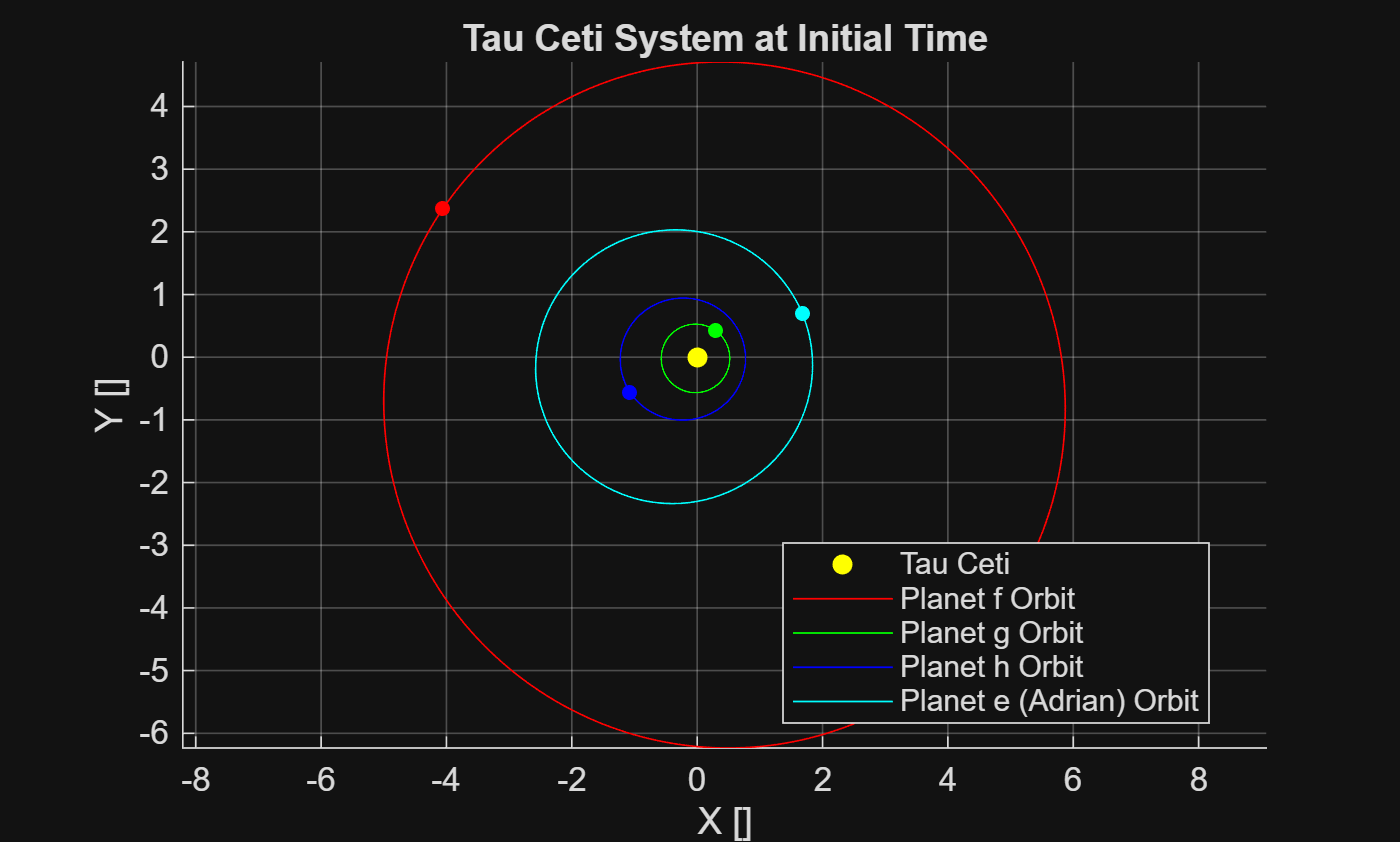

% Define true anomaly range for full orbit lines
thetastar = linspace(0, 2*pi, 1000);

% Initialize 2D Figure
figure;
hold on;
grid on;
axis equal;

% Plot Tau Ceti at origin
scatter(0, 0, 36, 'y', 'filled', DisplayName = "Tau Ceti");

orbitplot2D(planet_f.a, planet_f.e, thetastar + planet_f.theta_star, planet_f.w, "Planet f Orbit", color = "r", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(planet_g.a, planet_g.e, thetastar + planet_g.theta_star, planet_g.w, "Planet g Orbit", color = "g", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(planet_h.a, planet_h.e, thetastar + planet_h.theta_star, planet_h.w, "Planet h Orbit", color = "b", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(planet_e.a, planet_e.e, thetastar + planet_e.theta_star, planet_e.w, "Planet e (Adrian) Orbit", color = "c", r_scale = star.l, Marker = "o", MarkerSize = 4)

% Labels and Formatting
xlabel('X []');
ylabel('Y []');
title('Tau Ceti System at Initial Time');
legend('Location', 'best');
hold off;

## Propagate Orbits into the Future

To propagate the orbits we must use the mean anomaly M

Propagating orbits is essential to any mission design

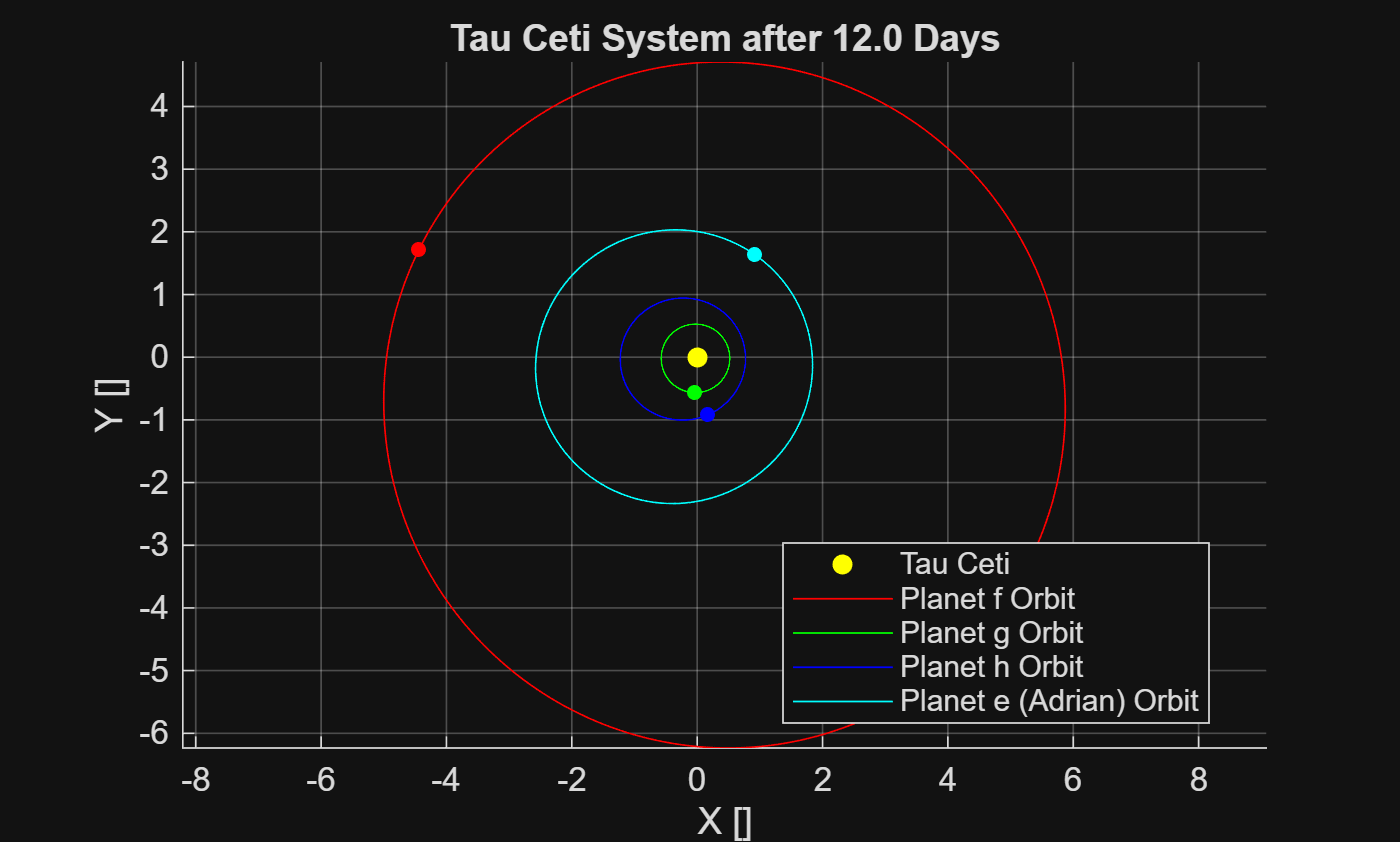

% Define propagation time
t_propagate = day_to_sec(12);

% Let's make a function to propagate an orbit to make our lives easier
function [thetastar_f] = propagate_conic_kep(orbiting_body, mu, t_prop)
    % First convert initial true anomaly into mean anomaly
    M_0 = eccentric_to_mean_anomaly(true_to_eccentric_anomaly(orbiting_body.theta_star, orbiting_body.e), orbiting_body.e);

    % Calculate mean motion
    n = sqrt(mu / orbiting_body.a ^ 3);

    % Calculate change in mean anomaly
    dM = n * t_prop;

    % Get final mean anomaly
    M_f = M_0 + dM;

    % Convert back to true anomaly
    thetastar_f = eccentric_to_true_anomaly(mean_to_eccentric_anomaly(M_f, orbiting_body.e), orbiting_body.e);
end

% Now call our function
thetastarf_f = propagate_conic_kep(planet_f, star.mu, t_propagate);
thetastarf_g = propagate_conic_kep(planet_g, star.mu, t_propagate);
thetastarf_h = propagate_conic_kep(planet_h, star.mu, t_propagate);
thetastarf_e = propagate_conic_kep(planet_e, star.mu, t_propagate);

% Plot new locations
% Initialize 2D Figure
figure;
hold on;
grid on;
axis equal;

% Plot Tau Ceti at origin
scatter(0, 0, 36, 'y', 'filled', DisplayName = "Tau Ceti");

orbitplot2D(planet_f.a, planet_f.e, thetastar + thetastarf_f, planet_f.w, "Planet f Orbit", color = "r", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(planet_g.a, planet_g.e, thetastar + thetastarf_g, planet_g.w, "Planet g Orbit", color = "g", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(planet_h.a, planet_h.e, thetastar + thetastarf_h, planet_h.w, "Planet h Orbit", color = "b", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(planet_e.a, planet_e.e, thetastar + thetastarf_e, planet_e.w, "Planet e (Adrian) Orbit", color = "c", r_scale = star.l, Marker = "o", MarkerSize = 4)

% Labels and Formatting
xlabel('X []');
ylabel('Y []');
title(sprintf('Tau Ceti System after %.1f Days', sec_to_day(t_propagate)));
legend('Location', 'best');
hold off;

## Planet g to Planet h Transfer

Given some transfer time, we want to calculate the transfer between the planets and what departure from and arrival to the planets looks like

### Interplanetary Transfer

We will use a Lambert solver to calculate a tranfser which satisfies our constraints on the planetary positions at departure and arrival. There are multiple solutions usually (clockwise vs counterclockwise) but we will pick the transfer which goes counterclockwise which is the direction we are saying all the planets go in

**NOTE:** to use the lambert solver, all distances and times have to be nondimensionalized so that the gravitational parameter of the central body is 1 (so divide distances by star.l and times by star.t)

t0 = day_to_sec(10); % Departure time
ToF = day_to_sec(10); % Time of flight for transfer

% Calculate the transfer angle, TA, for the transfer (change in true anomaly along transfer orbit)
theta_1 = propagate_conic_kep(planet_g, star.mu, t0) + planet_g.w; % Initial latitude
theta_2 = propagate_conic_kep(planet_h, star.mu, t0 + ToF) + planet_h.w; % Final latitude
TA = wrapTo2Pi(theta_2 - theta_1); % [rad] Make sure we get the right angle by using wrap function
fprintf(sprintf("Transfer Angle is %.3f degrees", rad2deg(TA)))

Transfer Angle is 131.309 degrees

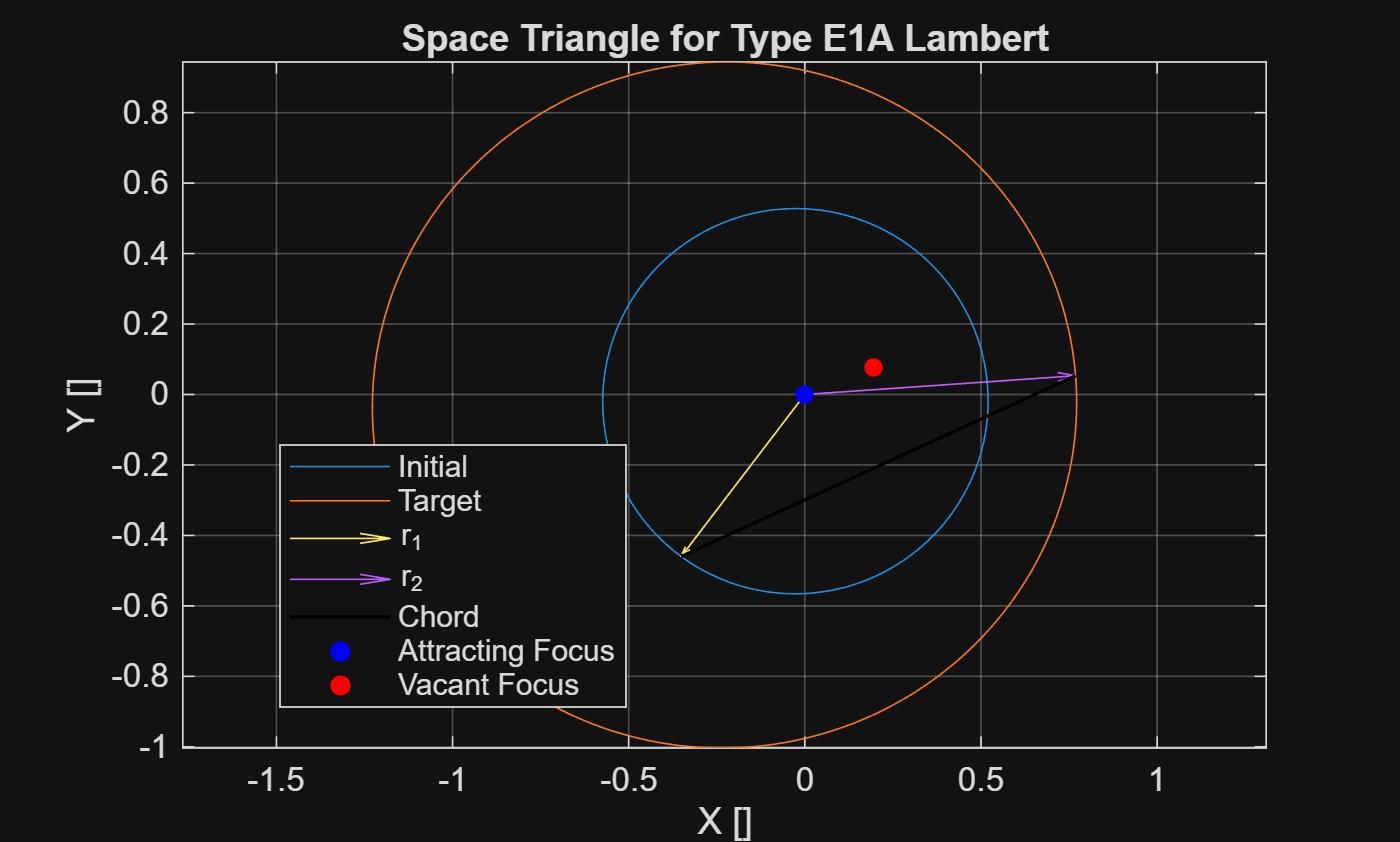

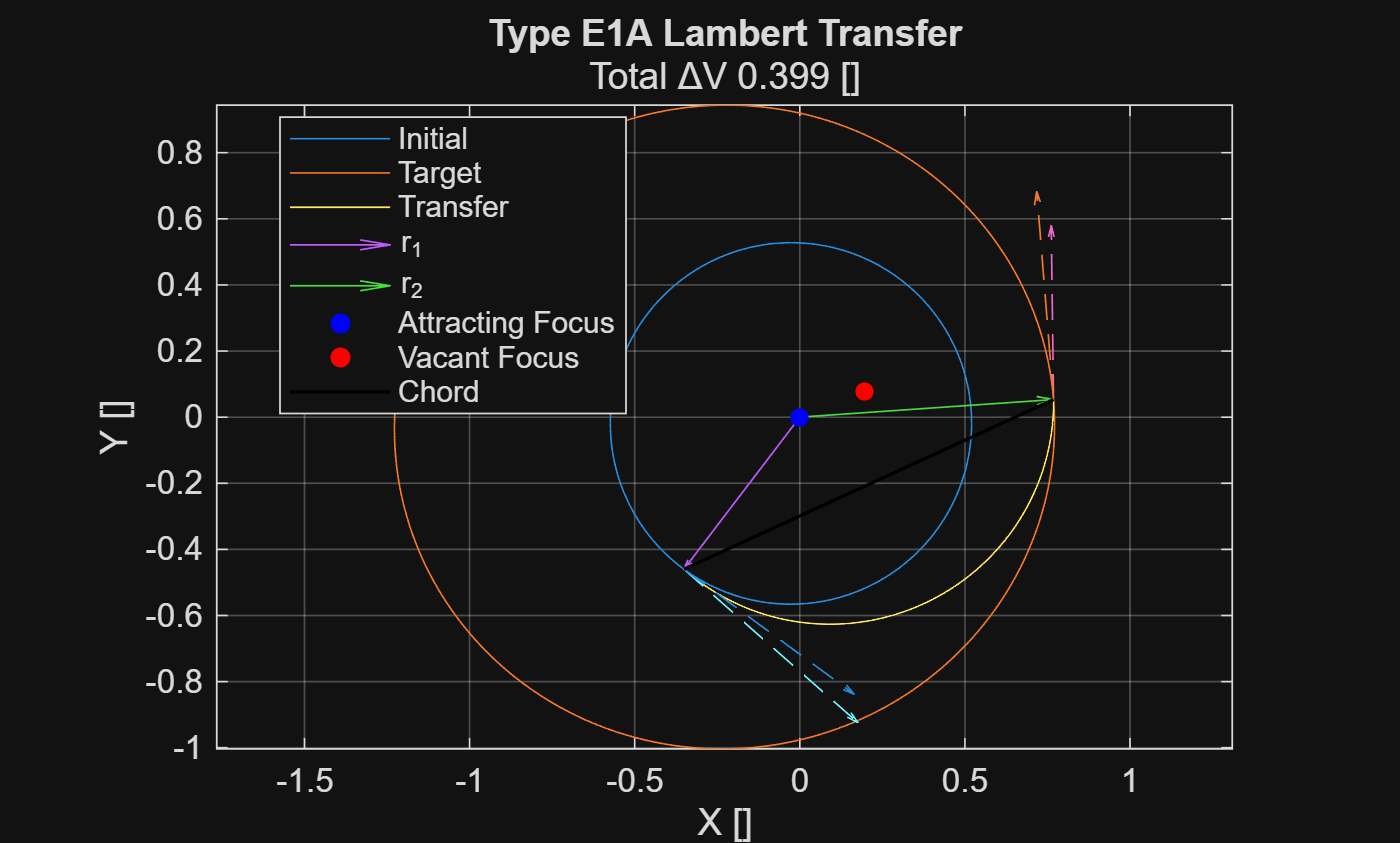


% Calculate initial radius and final orbital radius
r_1 = planet_g.a * (1 - planet_g.e ^ 2) / (1 + planet_g.e * cos(theta_1 - planet_g.w));
r_2 = planet_h.a * (1 - planet_h.e ^ 2) / (1 + planet_h.e * cos(theta_2 - planet_h.w));
% Define initial orbit (minus) and final orbit (plus)
minus_orbit_info.a = planet_g.a / star.l;
minus_orbit_info.e = planet_g.e;
minus_orbit_info.w = planet_g.w;
minus_orbit_info.ascension = sign(wrapToPi(theta_1 - planet_g.w)); % Is on ascending half of orbit or descending half?
plus_orbit_info.a = planet_h.a / star.l;
plus_orbit_info.e = planet_h.e;
plus_orbit_info.w = planet_h.w;
plus_orbit_info.ascension = sign(wrapToPi(theta_2 - planet_h.w)); % Is on ascending half of orbit or descending half?

% Calculate transfer
[a, lambert_type, space_triangle_info, transfer_info, lambert_solve_info, minus_orbit_info, plus_orbit_info] = lambert_arc(r_1 / star.l, r_2 / star.l, TA, ToF / star.t, minus_orbit_info, plus_orbit_info);

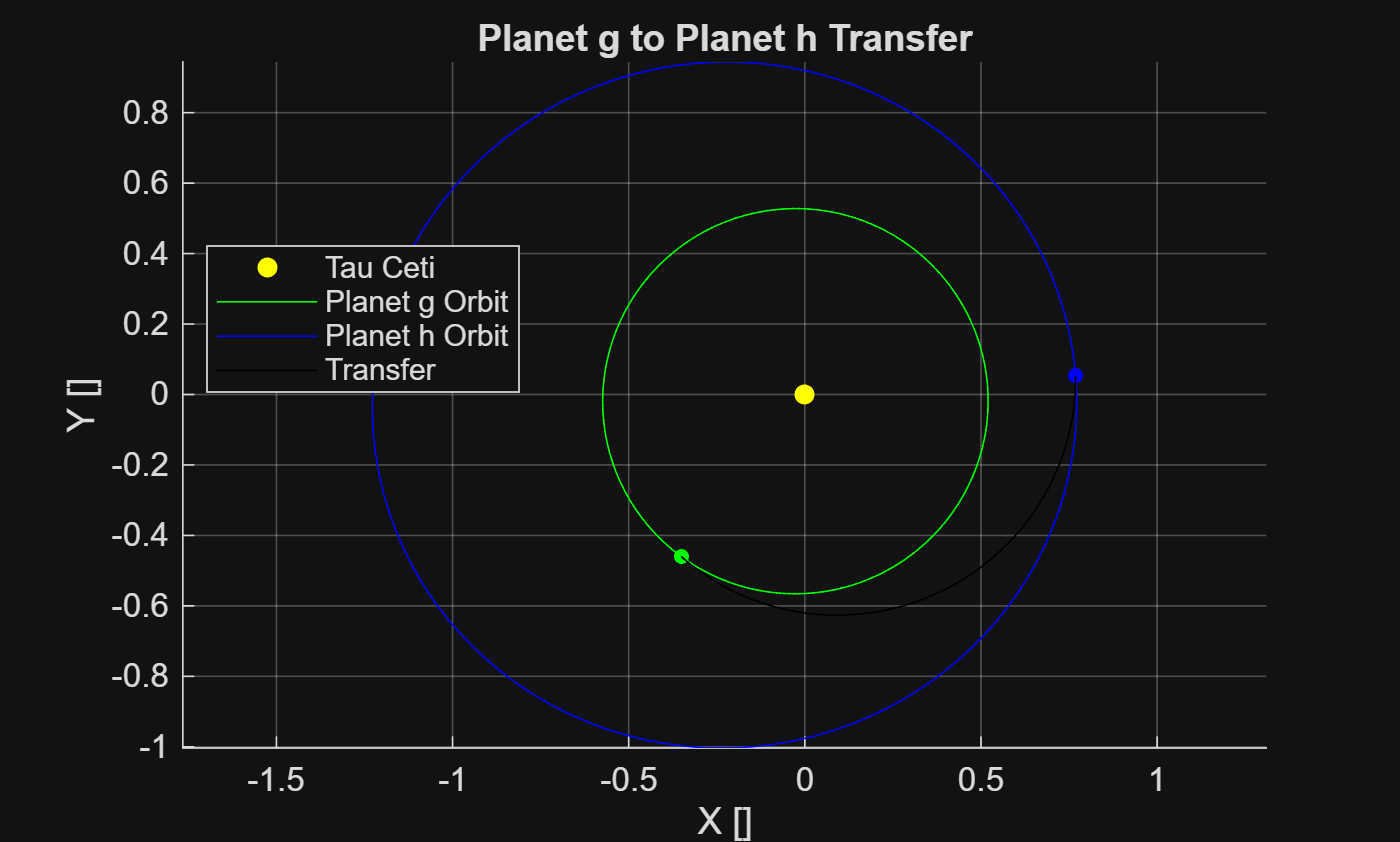

% Plot using our names

% Plot new locations
% Initialize 2D Figure
figure;
hold on;
grid on;
axis equal;

% Plot Tau Ceti at origin
scatter(0, 0, 36, 'y', 'filled', DisplayName = "Tau Ceti");

orbitplot2D(planet_g.a, planet_g.e, thetastar + transfer_info.maneuver_1.thetastar(1), planet_g.w, "Planet g Orbit", color = "g", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(planet_h.a, planet_h.e, thetastar + transfer_info.maneuver_2.thetastar(2), planet_h.w, "Planet h Orbit", color = "b", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(transfer_info.a, transfer_info.e, linspace(transfer_info.maneuver_1.thetastar(2), transfer_info.maneuver_1.thetastar(2) + TA, 200), transfer_info.w, "Transfer", color = "k")

% Labels and Formatting
xlabel('X []');
ylabel('Y []');
title('Planet g to Planet h Transfer');
legend('Location', 'best');
hold off;


% Here is all the info for the transfer
transfer_info

transfer_info = struct with fields:
                      a: 0.6723
    delta_conic_anomaly: 2.3154
                      p: 0.6559
                      e: 0.1559
                      w: 3.5215
             maneuver_1: [1×1 struct]
             maneuver_2: [1×1 struct]
               total_dV: 0.3986
          rvec_1_planar: [2×1 double]
          rvec_2_planar: [2×1 double]
               lagrange: [1×1 struct]
          vvec_1_planar: [2×1 double]
          vvec_2_planar: [2×1 double]
            phase_angle: 1.2842
                    r_D: 0.5785
                    r_A: 0.7703


### Planet g Departure

Now we need to find how to leave planet g to get onto our transfer trajectory.

% Initial (circular) orbit around planet g
R_park_g = 120; % [km]
r_park_g = R_park_g + planet_g.R;

% Info about the difference between the initial orbit and the transfer
% orbit at the departure point was already calculated using the
% 'planar_maneuver.m' function - but all values are nondimensionalized so
% be careful!
transfer_info.maneuver_1 % Difference between orbits at departure

ans = struct with fields:
           dV: 0.1743
        alpha: 0.8027
            v: [2×1 double]
        gamma: [2×1 double]
    thetastar: [-2.8394 0.5391]


vinf_g_dep = transfer_info.maneuver_1.dV * star.v % Relative velocity at departure - make sure to dimensionalize!

vinf_g_dep = 9.4154

% Calculate departure hyperbola parameters
a_h_dep = -planet_g.mu / vinf_g_dep ^ 2;
e_h_dep = 1 - r_park_g / a_h_dep

e_h_dep = 2.4411

% Find when to leave the parking orbit
alpha_dep = transfer_info.maneuver_1.gamma(2) - transfer_info.maneuver_1.gamma(1) % Angle from the planet's velocity vector we need to depart on

alpha_dep = 0.0894

departure_angle = acos(1 / e_h_dep) + pi; % eta, relative to the local horizon of Planet g around the Tau Ceti 
fprintf(sprintf("Departure angle is %.1f degrees", rad2deg(departure_angle)))

Departure angle is 245.8 degrees

% Calculate the maneuver to get into the departure hyperbola
v_park_g = sqrt(planet_g.mu / r_park_g);
v_h_dep = vis_viva(a_h_dep, r_park_g, planet_g.mu);
dV_dep = v_h_dep - v_park_g;
fprintf(sprintf("Departure delta V from Planet g is %.3f km / s", dV_dep))

Departure delta V from Planet g is 6.706 km / s

We can see that the actual delta V needed to get onto the transfer orbit is less than the relative velocity between the transfer orbit and the Planet g because we have some initial relative velocity with Planet g because we are orbiting it

Now let's plot the departure from Planet g

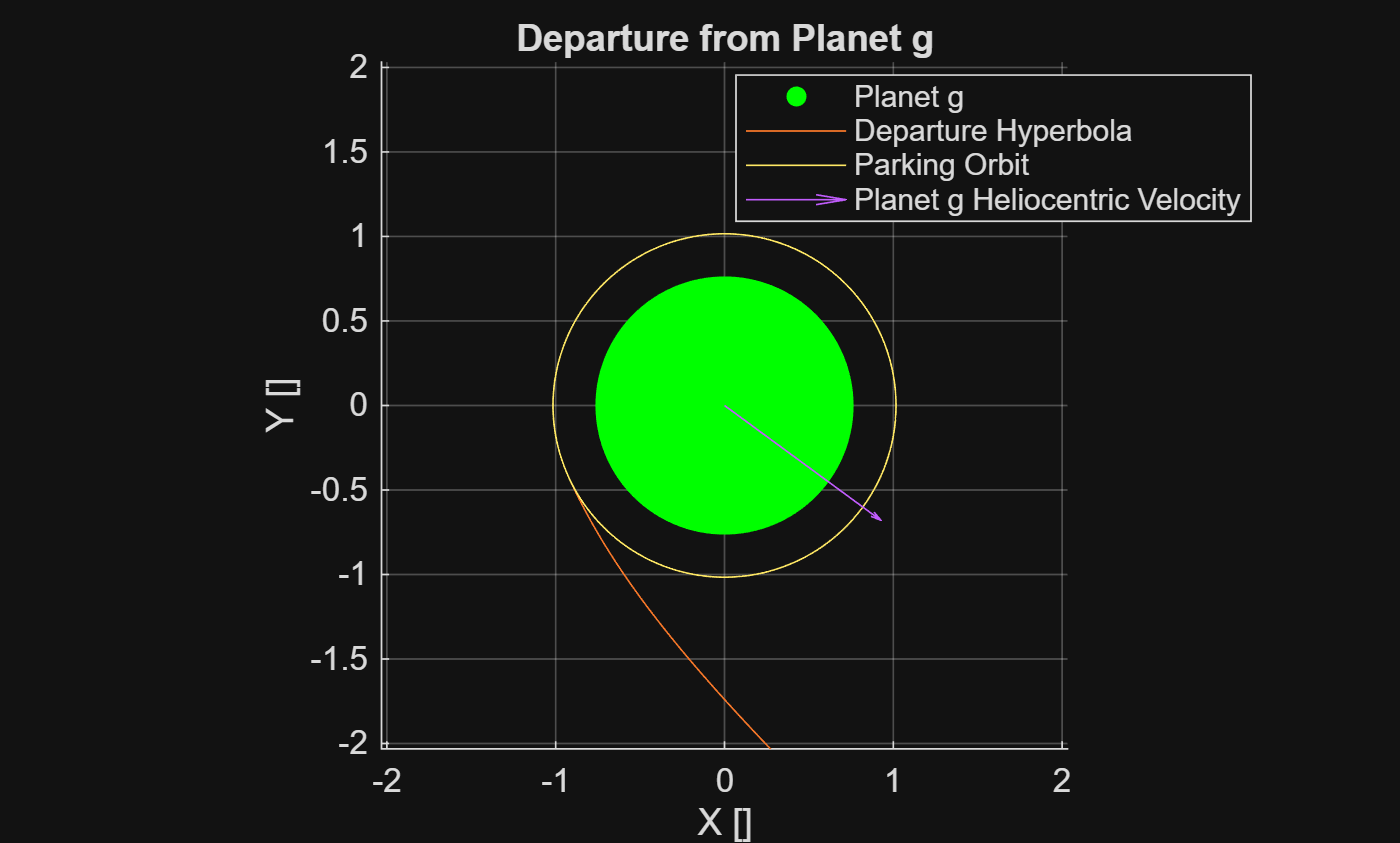

% Plot departure
% Initialize 2D Figure
figure;
hold on;
grid on;
axis equal;

% Plot Planet g at origin
scatter(0, 0, 6000, 'g', 'filled', DisplayName = "Planet g");

thetastar_h = linspace(0, deg2rad(90), 200); % Make sure to limit the plotting range for hyperbolas...

plot_angle_dep = atan2(transfer_info.vvec_1_planar(2), transfer_info.vvec_1_planar(1)); % Shift angle so it matches plot above
orbitplot2D(a_h_dep, e_h_dep, thetastar_h, departure_angle + plot_angle_dep, "Departure Hyperbola", r_scale = planet_g.R)
orbitplot2D(r_park_g, 0, thetastar, 0, "Parking Orbit", r_scale = planet_g.R)
quiver(0, 0, minus_orbit_info.vvec(1), minus_orbit_info.vvec(2), DisplayName = "Planet g Heliocentric Velocity")
xlim([-r_park_g * 2, r_park_g * 2] / planet_g.R)
ylim([-r_park_g * 2, r_park_g * 2] / planet_g.R)

% Labels and Formatting
xlabel('X []');
ylabel('Y []');
title('Departure from Planet g');
legend('Location', 'best');
hold off;

### Planet h Arrival

We could go into a parking orbit around Planet h, but this would be the same process as with the departure from g except we arrive along the hyperbola

Instead, let's calculate what a gravity assist around Planet h looks like

r_pfb_h = planet_h.R * 1.1; % Flyby radius
vinf_h_arr = transfer_info.maneuver_2.dV * star.v % Relative velocity at arrival - make sure to dimensionalize!

vinf_h_arr = 12.1196

% Calculate arrival hyperbola parameters
a_h_arr = -planet_h.mu / vinf_h_arr ^ 2;
e_h_arr = 1 - r_pfb_h / a_h_arr

e_h_arr = 3.5854

delta = 2 * asin(1 / e_h_arr) % [rad] Could also pick positive delta

delta = 0.5653

fprintf(sprintf("Turn angle at Planet h gravity assist is %.1f degrees", rad2deg(delta)))

Turn angle at Planet h gravity assist is 32.4 degrees

dV_GA = 2 * vinf_h_arr * sin(delta / 2)

dV_GA = 6.7606

v_minus = transfer_info.maneuver_2.v(1) * star.v

v_minus = 56.8978

v_planet_h_arr = transfer_info.maneuver_2.v(2) * star.v; % Retrieve Planet h's velocity at encounter
r_plus = space_triangle_info.r_2; % Still have planet's position after encounter
v_plus = sqrt(v_planet_h_arr ^ 2 + vinf_h_arr ^ 2 - 2 * vinf_h_arr * v_planet_h_arr * cos(delta))

v_plus = 58.3966

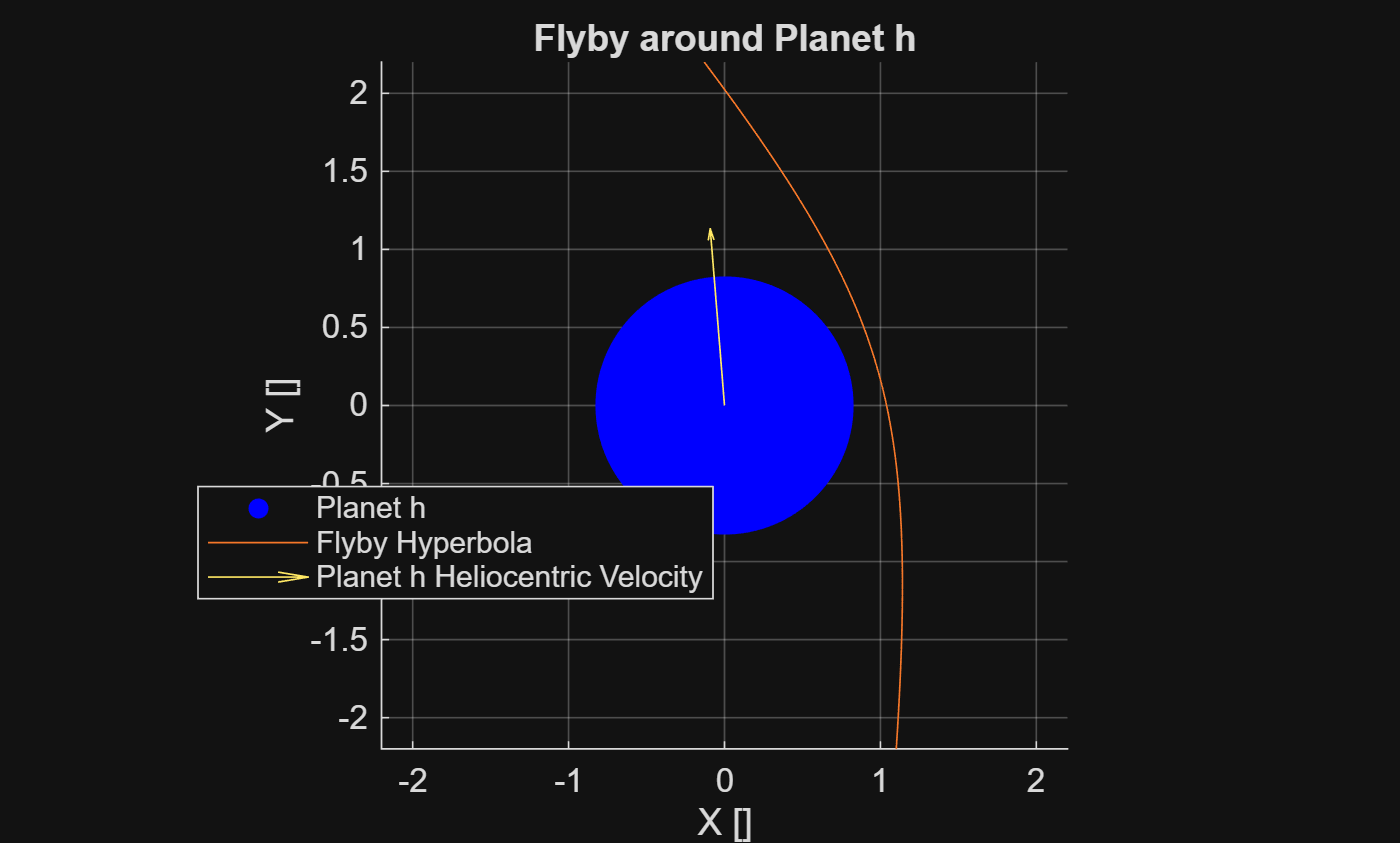



% Plot gravity assist
% Initialize 2D Figure
figure;
hold on;
grid on;
axis equal;

% Plot Planet g at origin
scatter(0, 0, 6000, 'b', 'filled', DisplayName = "Planet h");

thetastar_h = linspace(deg2rad(-90), deg2rad(90), 200); % Make sure to limit the plotting range for hyperbolas...

departure_angle = 2 * pi - acos(1 / e_h_arr) * sign(delta);
plot_angle_dep = atan2(transfer_info.vvec_2_planar(2), transfer_info.vvec_2_planar(1)); % Shift angle so it matches plot above
orbitplot2D(a_h_dep, e_h_dep, thetastar_h, departure_angle + plot_angle_dep, "Flyby Hyperbola", r_scale = planet_h.R)
quiver(0, 0, plus_orbit_info.vvec(1), plus_orbit_info.vvec(2), DisplayName = "Planet h Heliocentric Velocity")
xlim([-r_pfb_h * 2, r_pfb_h * 2] / planet_h.R)
ylim([-r_pfb_h * 2, r_pfb_h * 2] / planet_h.R)

% Labels and Formatting
xlabel('X []');
ylabel('Y []');
title('Flyby around Planet h');
legend('Location', 'best');
hold off;